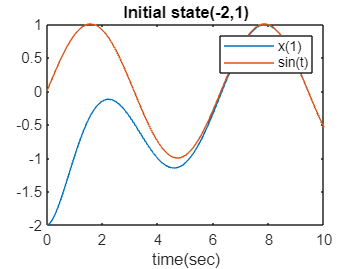

%Simulating the results

tstart = 0;
tend = 10;
dt = 0.01;
n = 1000;

tspan = transpose(linspace(tstart,tend,n));
xinit = [-2 1]; %initial values of states

[t,x] = ode45(@integratingfunc_SpringMass_system, tspan, xinit);
plot(t,x(:,1),t,sin(t));
title("Initial state(-2,1)")
legend(["x(1)","sin(t)"])
xlabel("time(sec)")

function dxdt = integratingfunc_SpringMass_system(t,x)
%INTEGRATINGFUNC_SPRINGMASS_SYSTEM Summary of this function goes here
%   Detailed explanation goes here

K = [1 2];              %Gain
z(1) = x(1);            %Normalized state coordinate
z(2) = x(2) + sin(x(1));
r(1) = sin(t);          %Reference variable
r(2) = cos(t);
e(1) = z(1) - r(1);     %Error variable
e(2) = z(2) - r(2);
gam = 1;    %Taking scalar gama as 1
alp = -(1/gam)*((x(1)^2)+(x(2)*cos(x(1)))+(sin(x(1))*cos(x(1))));   %alpha(x)
%Input:
u = (1/gam)*(-(K(1)*e(1))-(K(2)*e(2))-sin(t)) + alp;

dxdt = zeros(2,1);
dxdt(1) = x(2) + sin(x(1));
dxdt(2) = (x(1)^2) + (gam*u);
end